k = 4.66;
m1 = 0.0917;
m2 = 0.0765;
A = [0 1 0 0; -2*k/m1 0 k/m1 0; 0 0 0 1; k/m2 0 -k/m2 0];
x1_0 = 100;
x2_0 = 50;

T = 10;
N = 1000;
dt = T/N;
t = 0 : dt : T;

[x1, x2] = IEMsolver(A, x1_0, x2_0, T, N)

x1 =   100.0000   99.6189   98.4778   96.5907   93.9806   90.6794   86.7271   82.1718   77.0686   71.4790   65.4699   59.1131   52.4838   45.6599   38.7208   31.7465   24.8163   18.0076   11.3954    5.0506   -0.9603   -6.5766  -11.7440  -16.4152  -20.5508  -24.1193  -27.0982  -29.4737  -31.2408  -32.4038  -32.9757  -32.9783  -32.4415  -31.4029  -29.9076  -28.0068  -25.7577  -23.2221  -20.4657  -17.5572  -14.5670  -11.5665   -8.6265   -5.8167   -3.2043   -0.8533    1.1769    2.8321    4.0641    4.8315


x2 =    50.0000   50.1523   50.6075   51.3560   52.3816   53.6620   55.1695   56.8705   58.7268   60.6959   62.7316   64.7847   66.8038   68.7361   70.5280   72.1260   73.4779   74.5328   75.2429   75.5631   75.4529   74.8760   73.8016   72.2047   70.0665   67.3746   64.1236   60.3153   55.9582   51.0682   45.6680   39.7870   33.4613   26.7326   19.6483   12.2610    4.6273   -3.1923  -11.1347  -19.1345  -27.1250  -35.0391  -42.8101  -50.3725  -57.6631  -64.6212  -71.1899  -77.3168  -82.9541  -88.0600


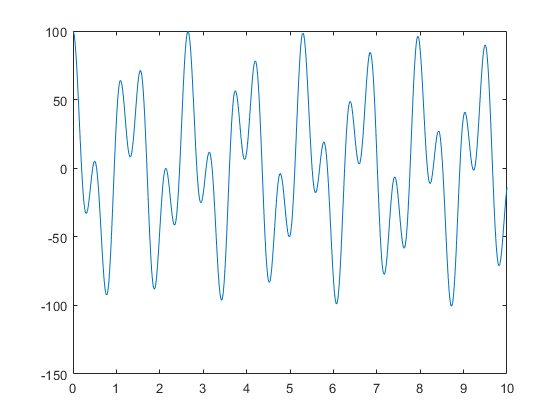



plot(t, x1)

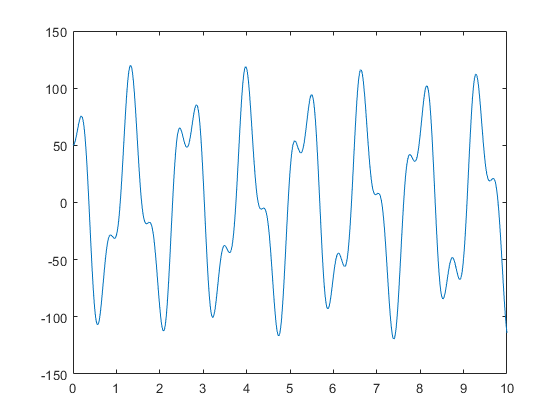

plot(t, x2)


eig(A)

ans =    0.0000 +11.8542i
   0.0000 -11.8542i
   0.0000 + 4.6935i
   0.0000 - 4.6935i


function [x1, x2] = IEMsolver(A, x1_0, x2_0, T, N)
    dt = T/N;
    t = 0 : dt : T;
    SOL = NaN(4, length(t));
    SOL(:,1) = [x1_0 0 x2_0 0]';
    for i = 2:length(t)
        m_prev = A*SOL(:,i-1);
        sol_cur = SOL(:,i-1) + A*SOL(:,i-1).*dt;
        m_cur = A*sol_cur;
        S = (m_prev + m_cur) ./ 2;
        SOL(:,i) = SOL(:,i-1) + S.*dt;
    end
    x1 = SOL(1,:);
    x2 = SOL(3,:);
 end
    